# EMAT30007 Applied Statistics

# Worksheet 5: Linear Models (Simple Linear Regression)

## Nikolai Bode

This worksheet focusses on simple linear regression models covered in lecture 5. These models take the general form: $Y_i=\beta_0+\beta_1 x_i  + \epsilon_i$.

We will explore three data sets in this worksheet. The first two are from real-world studies and the last one is a famous statistical data set (references are given in square brackets):

(1) DRILLROCK.csv

[Penner, R., Watts D. G. (1991). "Mining information". The American Statistician. 45(1): 6]

(2) APPLIANCES.csv

[Candanedo, L. M., Feldheim, V., Deramaix, D. (2017) "Data driven prediction models of energy use of appliances in a low-energy house". Energy and Buildings, Volume 140, 1 April 2017, Pages 81-97]

(3) ANSCOMBE.txt

[Anscombe, F. J. (1973). "Graphs in Statistical Analysis". American Statistician. 27 (1): 17–21]

... you can download all of the data sets on Blackboard.

## (1) Dataset DRILLROCK

This data is from a rock drilling experiment. There are two processes for hydraulic drilling of rock: dry drilling and wet drilling. In a dry hole, compressed air is forced down the drill rods to flush the cuttings and drive the hammer. I a wet hole, water is used instead of air. An experiment was conducted to determine whether the time it takes to dry drill a distance of 5 feet in rock increases with depth. The results for one portion of the experiment are provided in the file.

***1.1. Read in the data, see how many data points there are and plot a scatter plot of the data.***

% read data from file:
delimiterIn = ',';
A = importdata('DRILLROCK.csv',delimiterIn);

% how many data points are there?
A.data;
size(A.data)

ans =     17     2


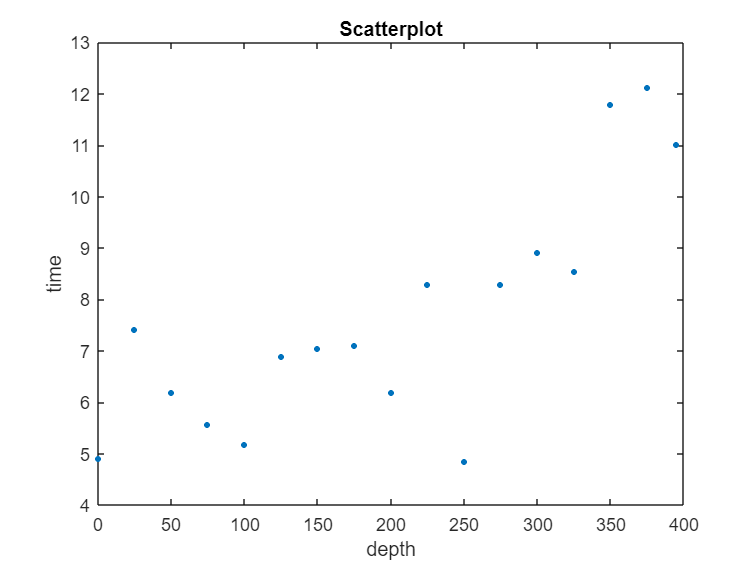

%% plot scatterplots
clf
x = A.data(:,1); % depth data
y = A.data(:,2); % time data
plot(x,y,'.', 'MarkerSize',10)
title('Scatterplot') % title for plot
xlabel('depth') % x-axis label
ylabel('time') % y-axis label

There are $n=17$ data points and from the scatterplot is already looks like there is a relationship between depth and time.

***1.2. Fit a simple linear model with intercept to this data.***

To demonstrate the model fitting process, we will use three different approaches in Matlab to fit the model. Of course, we could simply use ready-made model fitting tools in Matlab (as we will do most of the time), but it is instructive to see how model fitting works. The general structure of simple linear models is given above and in the lecture notes. We will use 'depth' as an explanatory variable and 'time' as our response variable.

We begin with the first method using the *exact equations* for estimating the model parameters, $\hat{\beta} = (X'X)^{-1}X'Y$ and $\hat{\sigma}^2 = \frac{1}{n-2}(Y-X\hat{\beta})'(Y-X\hat{\beta})$. In Matlab `X' `is the transpose of a matrix `X` and `inv(X)` gives the inverse of a matrix.

Y = y;
% define the matrix X. Don't forget about the intercept.
X = [ones(17,1) x];

beta_hat = inv(X'*X) * X'*Y

beta_hat =     4.7896
    0.0144


n = length(A.data);

sigma2 = 1 / (n -2) * (Y - X*beta_hat)' * (Y-X*beta_hat);
sigma = sqrt(sigma2)

sigma = 1.4322

You should find $\hat{\beta_0}=4.7896, \hat{\beta_1}=0.0144$ and $\hat{\sigma}=1.4322$.

In our next approach to fit the model, we perform a *numerical maximisation of the likelihood function*. Recall from lecture 5 that the likelihood function for our model is the product of the normal probability densities for all data points, given the model. In practice, rather than maximising this likelihood directly, we work with the log-likelihood. This avoids *underflow errors* where numbers become too small for the computer to cope with them (this happens a lot if we multiply many small probability densities). In fact, because Matlab has convenient options for finding the minimum of functions, we will find the minimum of the negative log-likelihood.

To streamline our code, we can write a separate Matlab file that computes the negative log-likelilhood for our model given parameter values and data (i.e. values for response and explanatory variables). This is provided for you and is called `negloglik.m`. Have a look at this file and make sure you understand what it does.

% define values for parameters that we use at the start of the optimisation.
% We have 3 parameters: sigma, beta_0, beta_1
% x0 is the same length as the vector 'paras' in the function 'negloglik'.
x0 = [sqrt(var(y)) 1 0];

% check that computing the negative log-likelihood using 'negloglik.m' works:
negloglik([1 2 0],1,2) % uses sigma=1, beta_0=2 and beta_1=0 for data: Y=1 and x=2.

ans = 1.4189

negloglik(x0,y,x) % uses starting values of parameters and all data.

ans = 110.2454

% maximum likelihood fit:
fun = @(s)negloglik(s,y,x); % this sets up the function we want to minimise.
s = fminsearch(fun,x0); % here we performe the optimisation
% (i.e. find parameters for which negloglik is minimal)

% The fitted parameters are stored in 's':
s(1) % sigma

ans = 1.3453

s(2) % beta_0

ans = 4.7896

s(3) % beta_1

ans = 0.0144

We (should) find the same values for $\hat{\beta_0}$ and $\hat{\beta_1}$. However, the variance estimate is different to the value of $\hat{\sigma}$ we found before. In fact, it is equal to $\frac{1}{n}(Y-X\hat{\beta})'(Y-X\hat{\beta})$. We say that the maximum likelihood estimator for the variance is *biased*. A detailed explanation for this is beyond the scope of the course, but notice that the difference between the estimate we use above and the maximum likelihood estimate will become negligible for large data sets (i.e. large $n$).

Fortunately, Matlab does all the hard work in fitting simple linear models for us. All we need to know are a few simple commands and how to use them:

% create a table for the data (x,y, defined above):
data = table(x,y,'VariableNames',{'depth','time'});
% show first few rows of table
data(1:5,:)

ans = 5×2 table
    depth    time
    _____    ____

       0      4.9
      25     7.41
      50     6.19
      75     5.57
     100     5.17


% fit simple linear model
m1 = fitlm(data, 'time~depth');

Note how the structure of the model is defined using the variable names of the table `data` we defined. The standard notation in Matlab is that '~' separates the response variable from the predictor. An intercept is included into the model by default.

The object `m1` stores a lot of useful information about the model fit (see https://uk.mathworks.com/help/stats/linearmodel-class.html) and we can obtain a fairly comprehensive report on the model simply by calling `m1`:

m1

m1 = Linear regression model:
    time ~ 1 + depth

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    _________    ______    __________

    (Intercept)      4.7896      0.66631    7.1882    3.1335e-06
    depth          0.014388    0.0028472    5.0533    0.00014286


Number of observations: 17, Error degrees of freedom: 15
Root Mean Squared Error: 1.43
R-squared: 0.63,  Adjusted R-Squared: 0.605
F-statistic vs. constant model: 25.5, p-value = 0.000143

An explanation for this output is provided in the lecture notes.

Before interpreting the parameter estimates and the hypothesis tests, we need to ensure our model is appropriate for the data (model checking).

***1.3. Compute the residuals for the model fit and use residual plots to check that no model assumptions are violated.***

In lecture 5, we discussed the assumptions we make when using simple linear models. One way to check these assumptions are not violated is to look at residual plots. Once we have fitted our model to the data and obtained parameter estimates, it is easy to compute residuals $\hat{\epsilon} = Y-X\hat{\beta}$. Compute residuals in this way. Plot their distribution (using `hist()`), to see if they roughly follow a normal distribution. In addition, plot the fitted values, $X\hat{\beta}$, against the residuals, to ensure homoscedasticity.

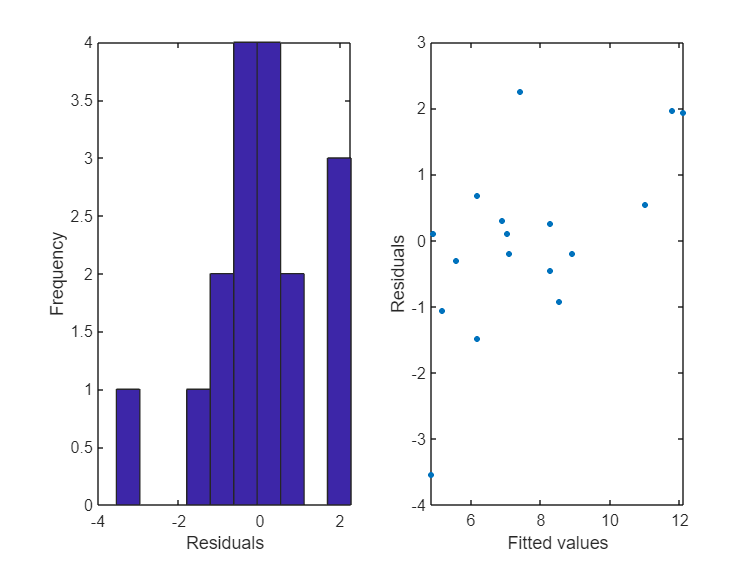

% use parameter estimates and data to find residuals.
resids = Y - X*beta_hat;

clf
subplot(1,2,1)
hist(resids)
xlabel('Residuals')
ylabel('Frequency')
% plot the residuals versus the fitted values
subplot(1,2,2)
plot(Y, resids, '.', 'MarkerSize', 10)
xlabel('Fitted values')
ylabel('Residuals')

In Matlab we can use a few simple commands to obtain the key residual plots. To show the residual plots discussed in lectures, you can use the following code:

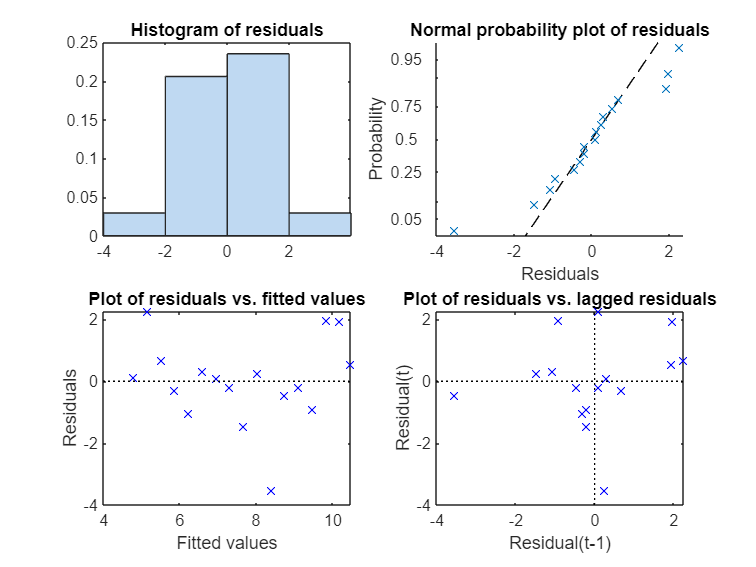

% plot distribution of residuals (for outliers etc.)
clf
subplot(2,2,1)
plotResiduals(m1)
% plot to check normality
subplot(2,2,2)
plotResiduals(m1,'probability')
% residuals versus fitted values (check for homoscedasticity)
subplot(2,2,3)
plotResiduals(m1,'fitted')
% auto-correlation (via lagged residuals)
subplot(2,2,4)
plotResiduals(m1,'lagged') % want no trend in this!

Looking at these residual plots, can you see any obvious reasons for why the model assumptions may not hold? 

Answer: overall, the model assumptions seem appropriate. The data form a fairly straight line in the normal probability plot and the histogram of the residuals is somewhat mound-shaped. There is no indication that the data are not normally distributed. The plot of the residuals against the fitted values does not show evidence for heteroscedasticity (e.g. funnel shape or a football shape). There is therefore no indication that the assumption of constant variance is violated. There is also no evidence that residuals are auto-correlated.

***1.4. Check the model fit visually***

We have ensured the model assumptions are appropriate. Now we need to check that the model fit is sensible. For simple linear regression models, it is always worth it to plot the model we have fitted alongside the data.

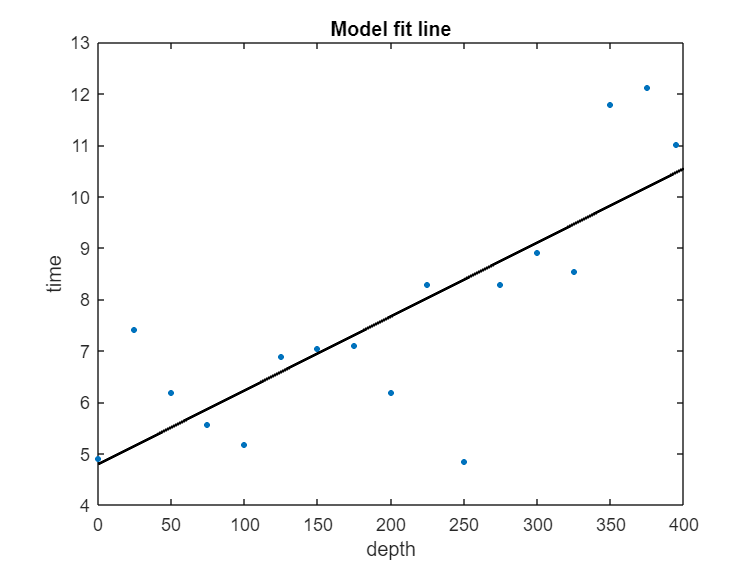

% check model fit:
clf
% plot the raw data:
plot(x,y,'.', 'MarkerSize', 10)
hold on
% plot model fit line using the estimates parameters:
xx = [0 400];
yy = [m1.Coefficients{1,1}+0*m1.Coefficients{2,1} m1.Coefficients{1,1}+400*m1.Coefficients{2,1}];
plot(xx,yy,'k','LineWidth',1.5)
xlabel('depth') % x-axis label
ylabel('time') % y-axis label
title('Model fit line')

This looks sensible, as the straight line appears to capture the trend in the data reasonably well.

We have discussed alternative measures for model fit in the lecture (e.g. $R^2$) and Matlab computes some of these automatically. We won't focus on these for now, as we will look at such measures in more detail in lecture 6 & worksheet 6.

***1.5. Does the time it takes to dry drill a distance of 5 feet in rock increase with depth?***

We have now fitted our model and checked it thoroughly. Now we can investigate the parameter estimates and interpret what they mean. To answer the question above, we look at the parameter estimate $\hat{\beta_1}$, or the slope of our model. It is positive, suggesting that as the depth increases, the time to drill 5 feet increases. We should formally test this assertion by computing a p-value for the null hypothesis $H_0: \beta_1=0$. While the result of this test is already provided as part of the Matlab output above, it is instructive to repeat this computation manually.

Use the formula for the T-statistic for the model parameter $\hat{\beta_1}$ given in the lecture notes and the cumulative distribution function of the Stdent's T-distribution in Matlab (`tcdf()`) to find the p-value for the hypothesis above.

% re-calculate the error estimate
sigmahat = sqrt((Y-X*beta_hat)'*(Y-X*beta_hat)/(17-2))

sigmahat = 1.4322

% calculate the quantity SS_xx
ssxx = sum((x-mean(x)).*(x-mean(x)))

ssxx = 2.5302e+05

% calculate T-value
T = (beta_hat(2) - 0) / (sigmahat/sqrt(ssxx))

T = 5.0533

m1.Coefficients{2,1}/m1.Coefficients{2,2}

ans = 5.0533

P = 2*(1-tcdf(T, 17-2))

P = 1.4286e-04

m1.CoefficientNames

ans = 1×2 cell array
    {'(Intercept)'}    {'depth'}


intercept_pvalue = m1.Coefficients{1,4}

intercept_pvalue = 3.1335e-06

depth_pvalue = m1.Coefficients{2,4}

depth_pvalue = 1.4286e-04

***1.6. Compute the prediction and estimation intervals for the model fit.***

We briefly covered this in lectures. Once we have fit a model to data, we can then use it to estimate the mean value of the response, or to predict the response, for a given value of the explanatory variable. The confidence intervals for prediction and estimation can easily be obtained in Matlab. The default are 95% confidence intervals.

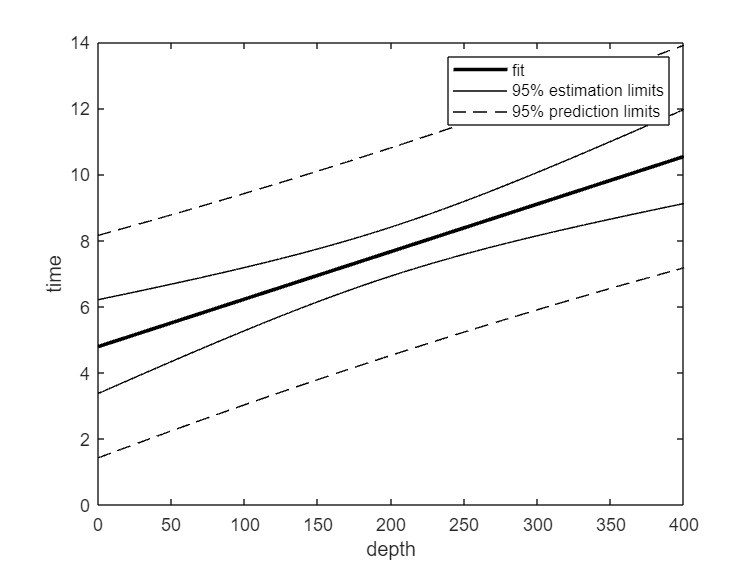

% prediction and estimation intervals:
xnew = 0:0.1:400;
% confidence bounds for fitted mean values (estimation)
[ypred,yci] = predict(m1,xnew','Prediction','curve');
% confidence bounds for new observations (prediction)
[ypred2,yci2] = predict(m1,xnew','Prediction','observation');

% plot these intervals:
xx = [0 400];
yy = [m1.Coefficients{1,1}+0*m1.Coefficients{2,1}...
    m1.Coefficients{1,1}+400*m1.Coefficients{2,1}];
clf
plot(xx,yy,'k','LineWidth',2) % Fit
% estimation and prediction limits
hold on
plot(xnew,yci(:,1),'k',xnew,yci2(:,1),'k--') 
plot(xnew,yci(:,2),'k',xnew,yci2(:,2),'k--')
legend('fit','95% estimation limits','95% prediction limits')
xlabel('depth') % x-axis label
ylabel('time') % y-axis label

Above, we have calculated estimation and prediction intervals for many values of the depth. Now compute these intervals for a value of the depth of 200 and 800. What is problematic about computing estimates or making predictions using the latter value of the depth?

vals = [200, 800]';
% confidence bounds for fitted mean values (estimation)
[ypred,yci] = predict(m1,vals,'Prediction','curve');
ypred

ypred =     7.6672
   16.2999


yci

yci =     6.9268    8.4076
   12.5824   20.0174


% confidence bounds for new observations (prediction)
[ypred2,yci2] = predict(m1,vals,'Prediction','observation');
ypred2

ypred2 =     7.6672
   16.2999


yci2

yci2 =     4.5260   10.8083
   11.4896   21.1101


## (2) Dataset APPLIANCES

This data was collected to investigate the energy use of appliances in low-energy buildings. The data set is from one house. Outside temperature and appliance energy use readings were taken every 10 minutes for about 4.5 months. Thus, there are a lot more data points than in the first data set and this quantity of data is more representative of what statistical analysis currently looks like.

Use the techniques we have covered so far to answer the following exercises. You can use the standard Matlab commands for this analysis.

***2.1. Read in the data, see how many data points there are and plot a scatter plot of the data.***

Looking at this data, do you think a simple linear model will describe the data well?

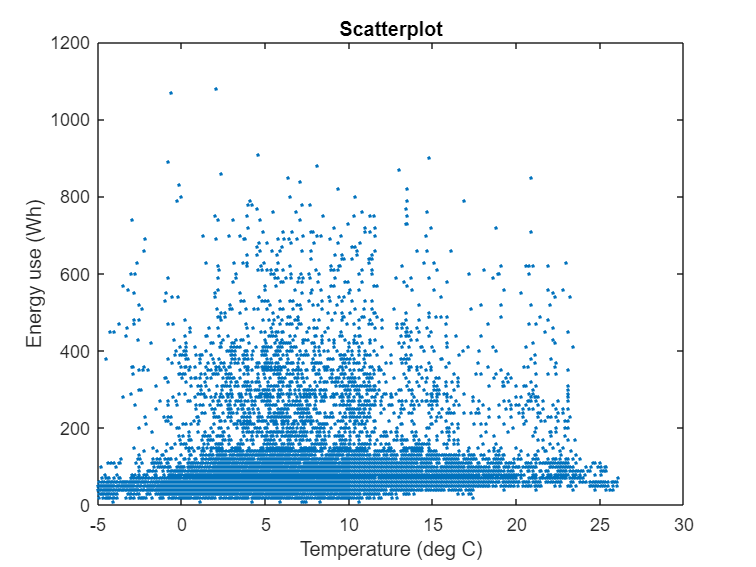

% read data from file:
delimiterIn = ',';
data = readtable('APPLIANCES.csv');

clf
x = data.Temperature_outside_celsius; % Temperature data
y = data.Appliances_energy_use_Wh; % Energy use data
plot(x, y, '.')
title('Scatterplot')
xlabel('Temperature (deg C)')
ylabel('Energy use (Wh)')

% fit simple linear model
m1 = fitlm(data, 'Appliances_energy_use_Wh~Temperature_outside_celsius')

m1 = Linear regression model:
    Appliances_energy_use_Wh ~ 1 + Temperature_outside_celsius

Estimated Coefficients:
                                   Estimate      SE       tStat       pValue  
                                   ________    _______    ______    __________

    (Intercept)                     83.526      1.2458    67.047             0
    Temperature_outside_celsius     1.9114     0.13655    13.998    2.6247e-44


Number of observations: 19735, Error degrees of freedom: 19733
Root Mean Squared Error: 102
R-squared: 0.00983,  Adjusted R-Squared: 0.00978
F-statistic vs. constant model: 196, p-value = 2.62e-44

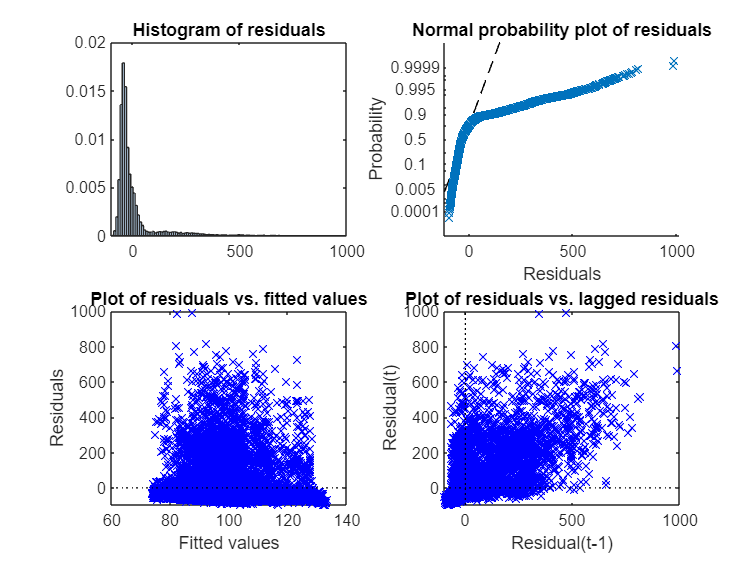

% plot distribution of residuals (for outliers etc.)
clf
subplot(2,2,1)
plotResiduals(m1)
% plot to check normality
subplot(2,2,2)
plotResiduals(m1,'probability')
% residuals versus fitted values (check for homoscedasticity)
subplot(2,2,3)
plotResiduals(m1,'fitted')
% auto-correlation (via lagged residuals)
subplot(2,2,4)
plotResiduals(m1,'lagged') % want no trend in this!

*Discussion of residual plots:*

The distribution of residuals does not look like a normal distribution. The peak around zero could be normally distributed, but there is another peak, making the distribution *bimodal*.

This non-normal distribution is also clearly indicated in the normal probability plot. We could speculate that outside temperature is not the only factor that explains energy use in the house. For example, time of day or day of the week could also be relevant.

Plotting fitted values versus residuals confirms our observation from the scatterplot of the data that there are many high-energy data points our model cannot explain.

Plotting residuals versus lagged residuals shows some evidence of autocorrelation in the residuals (i.e. the plot has some structure along the line indicating positive correlation). In some ways that it not surprising. The data set form a time series (readings every 10 minutes). Consecutive readings are therefore unlikely to be entirely independent (thin about appliances being switched on for >10 mins).

Overall, we have to be very careful with interpreting this model fit to the data. Some model assumptions clearly do not hold. This means that the theory we use may give miselading results.

***2.4. Check the model fit visually***

Having seen the residual plots we should re-think our modelling approach. However, it's good to practice. Once you've had a look at the model fit visually, you can also look at the Matlab summary of the model fit. Keeping all the limitations about the model fit in mind, do you think temperature is a factor in determining the energy usage in the house? 

% check model fit:
clf
% plot the raw data:
plot(x,y,'.', 'MarkerSize', 10)
hold on
% plot model fit line using the estimates parameters:
xx = [min(x) max(x)]

xx =    -5.0000   26.1000


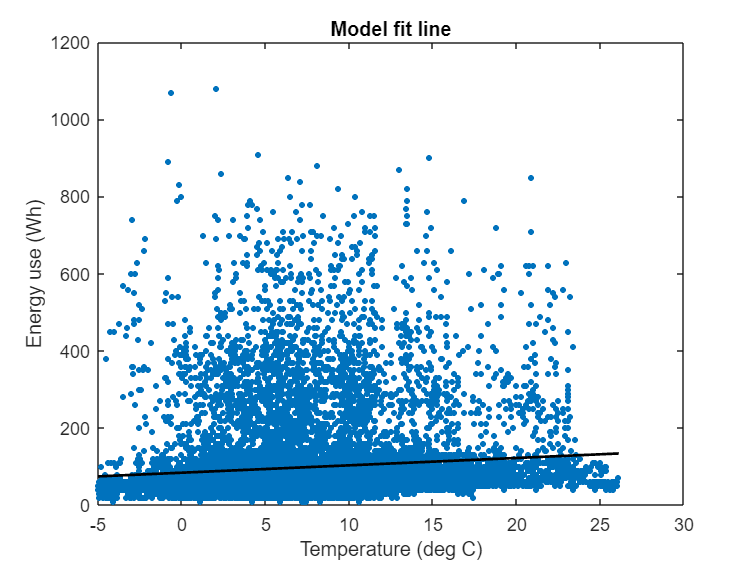

yy = [m1.Coefficients{1,1}+min(x)*m1.Coefficients{2,1} m1.Coefficients{1,1}+max(x)*m1.Coefficients{2,1}];
plot(xx,yy,'k','LineWidth',1.5)
xlabel('Temperature (deg C)')
ylabel('Energy use (Wh)')
title('Model fit line')

Thinking more broadly, if there is an effect, can we be sure that lower temperatures cause higher energy usage? Or could it be that temepratures are correlated with other factors (e.g. light levels) that are more important in determining the usage and energy consumption of appliances? Remember: *correlation does not imply causation!*

## (3) Dataset ANSCOMBE

This file actually contains four data sets. They were constructed in 1973 by the statistician Francis Anscombe to demonstrate both the importance of graphing data before analyzing it and the effect of outliers on statistical properties.

The file `ANSCOMBE.txt` has eight columns. The first two columns are the explanatory and response variables for the first data set, respectively. The third and fourth columns make up the second data set, and so forth.

***3.1. Read in the dat sets and fit a simple linear model to each of them.***

***3.2. Compare the model fits.***

***3.3. Plot scatterplots of the data sets with the fit lines of the corresponding models.***

Without looking at residual plots, do you think it's appropriate to use simple linear models to investigate all of the data sets?

% read data from file:
delimiterIn = ',';
data = readtable('ANSCOMBE.txt', 'Delimiter',delimiterIn);
m1 = fitlm(data, 'y1~x1')

m1 = Linear regression model:
    y1 ~ 1 + x1

Estimated Coefficients:
                   Estimate      SE       tStat      pValue  
                   ________    _______    ______    _________

    (Intercept)     3.0001      1.1247    2.6673     0.025734
    x1             0.50009     0.11791    4.2415    0.0021696


Number of observations: 11, Error degrees of freedom: 9
Root Mean Squared Error: 1.24
R-squared: 0.667,  Adjusted R-Squared: 0.629
F-statistic vs. constant model: 18, p-value = 0.00217

m2 = fitlm(data, 'y2~x2')

m2 = Linear regression model:
    y2 ~ 1 + x2

Estimated Coefficients:
                   Estimate      SE       tStat      pValue  
                   ________    _______    ______    _________

    (Intercept)     3.0009      1.1253    2.6668     0.025759
    x2                 0.5     0.11796    4.2386    0.0021788


Number of observations: 11, Error degrees of freedom: 9
Root Mean Squared Error: 1.24
R-squared: 0.666,  Adjusted R-Squared: 0.629
F-statistic vs. constant model: 18, p-value = 0.00218

m3 = fitlm(data, 'y3~x3')

m3 = Linear regression model:
    y3 ~ 1 + x3

Estimated Coefficients:
                   Estimate      SE       tStat      pValue  
                   ________    _______    ______    _________

    (Intercept)     3.0025      1.1245    2.6701     0.025619
    x3             0.49973     0.11788    4.2394    0.0021763


Number of observations: 11, Error degrees of freedom: 9
Root Mean Squared Error: 1.24
R-squared: 0.666,  Adjusted R-Squared: 0.629
F-statistic vs. constant model: 18, p-value = 0.00218

m4 = fitlm(data, 'y4~x4')

m4 = Linear regression model:
    y4 ~ 1 + x4

Estimated Coefficients:
                   Estimate      SE       tStat      pValue  
                   ________    _______    ______    _________

    (Intercept)     3.0017      1.1239    2.6708      0.02559
    x4             0.49991     0.11782     4.243    0.0021646


Number of observations: 11, Error degrees of freedom: 9
Root Mean Squared Error: 1.24
R-squared: 0.667,  Adjusted R-Squared: 0.63
F-statistic vs. constant model: 18, p-value = 0.00216

clf
tables = 
for i = 1:4
    subplot(2, 2, i)
    char_i = num2str(i)
    x = data.(['x' char_i])
    y = data.(['y' char_i])

    plot(x,y,'.', 'MarkerSize', 10)
    hold on
    % plot model fit line using the estimates parameters:
    xx = [min(x) max(x)]
    yy = [m1.Coefficients{1,1}+min(x)*m1.Coefficients{2,1} m1.Coefficients{1,1}+max(x)*m1.Coefficients{2,1}];